## Generate 4-QAM Image Data

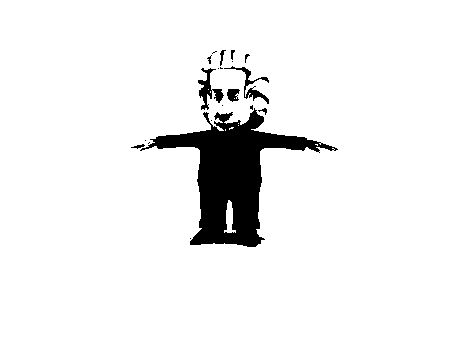

im = imread('data\einstein.jpg');
imBW = im2bw(im,.7);
figure;
imshow(imBW)

## Generate TX Data

clear;
hamming_on = 1;
picture = 'checkerboard';
%generate start sequence
input_image = strcat('data\',picture,'.jpg');
pilot_seq_len = 32; % length of known pilot sequence
%ending_seq_len = 32;
standard_packet_len = 100000;
Fs = 2000000; % sampling frequency

%generate RRC Pulse
T = 50; % Symbol Period
data_len = standard_packet_len * T;
span = 20;
rolloff = 0.5;
rrc = rcosdesign(rolloff,span,T, 'sqrt');   % creates a root-raised cosine 

[imBW,dataQ,data] = image_to_data(input_image,hamming_on);

if hamming_on
    txname = strcat('data\', picture, '_hamdan.dat');
else
    txname = strcat('data\', picture, '.dat');
end
txname

txname = 'data\checkerboard_hamdan.dat'

input = build_tx_file(txname, dataQ, pilot_seq_len, rrc, T, standard_packet_len)

input =   -0.7968 + 0.8074i
  -0.7878 + 0.7984i
  -0.7762 + 0.7867i
  -0.7621 + 0.7725i
  -0.7456 + 0.7557i
  -0.7266 + 0.7364i
  -0.7052 + 0.7145i
  -0.6815 + 0.6902i
  -0.6553 + 0.6634i
  -0.6270 + 0.6343i


## Decode RX Data

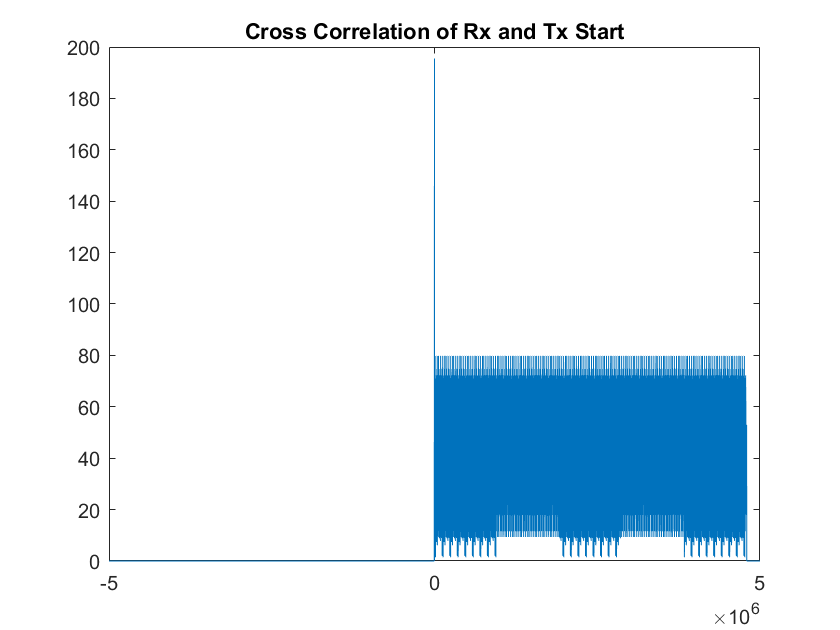

tx_pilot =   -0.1281 + 0.1298i
  -0.1266 + 0.1283i
  -0.1248 + 0.1265i
  -0.1225 + 0.1242i
  -0.1199 + 0.1215i
  -0.1168 + 0.1184i
  -0.1134 + 0.1149i
  -0.1095 + 0.1109i
  -0.1053 + 0.1066i
  -0.1008 + 0.1020i


startPos = 0

phi = -1.1935e-04

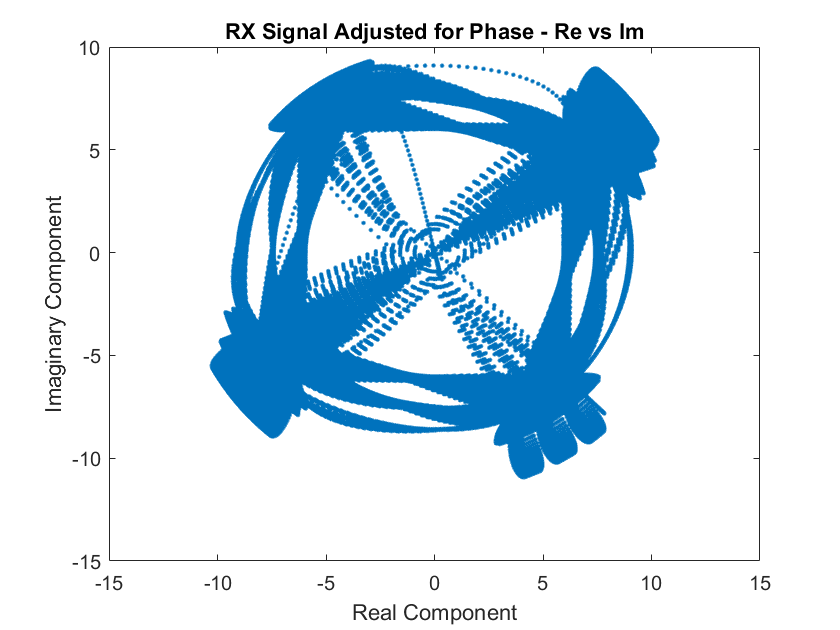

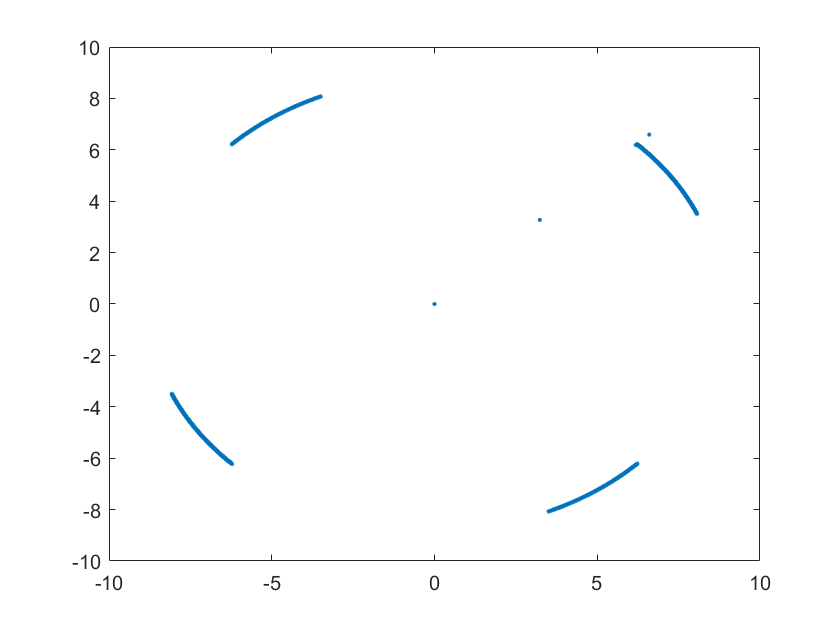

tx_ds =    0.9019 + 0.9054i
   0.8821 + 0.8229i
   0.8781 + 1.0141i
   0.8878 - 0.9925i
   0.8733 - 0.8036i
   0.8224 - 0.8326i
   1.0776 - 1.1064i
  -1.1839 + 1.1985i
   1.2439 - 1.1844i
  -1.2501 + 0.9998i


rx_ds =    3.2338 + 3.2719i
   6.5974 + 6.5926i
   6.1875 + 6.1874i
   6.1938 - 6.2475i
   6.2258 - 6.2152i
   6.2309 - 6.2128i
   6.2195 - 6.2238i
  -6.2259 + 6.2173i
   6.2212 - 6.2202i
  -6.2216 + 6.2241i


txname='data\checkerboard_hamdan.dat';
rxname = 'data\checkerboard_hamdan.dat';
figure;
[rxQ, errRate] = qpsk(txname, rxname, T, 2000000, data_len);   

errRate

errRate = 1.5005e-04

## Printing Image

rxQ = sign(real(rxQ)) + 1i*sign(imag(rxQ));
rxBinary = decodeQam(rxQ);

if hamming_on
    rxBinary = errorCorrect(rxBinary);
end
 
rows = bi2de(rxBinary(1:16),'left-msb');
cols = bi2de(rxBinary(17:32),'left-msb');

if mod(rows*cols,2) ~= 0
    dataRx = rxBinary(33:end-1);
else
    dataRx = rxBinary(33:end);
end
dataRx = dataRx(1:rows*cols)

dataRx =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


compute_qpsk_error(data,dataRx)

err_total = 1

ans = 4.5637e-06

dataRx =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


data =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


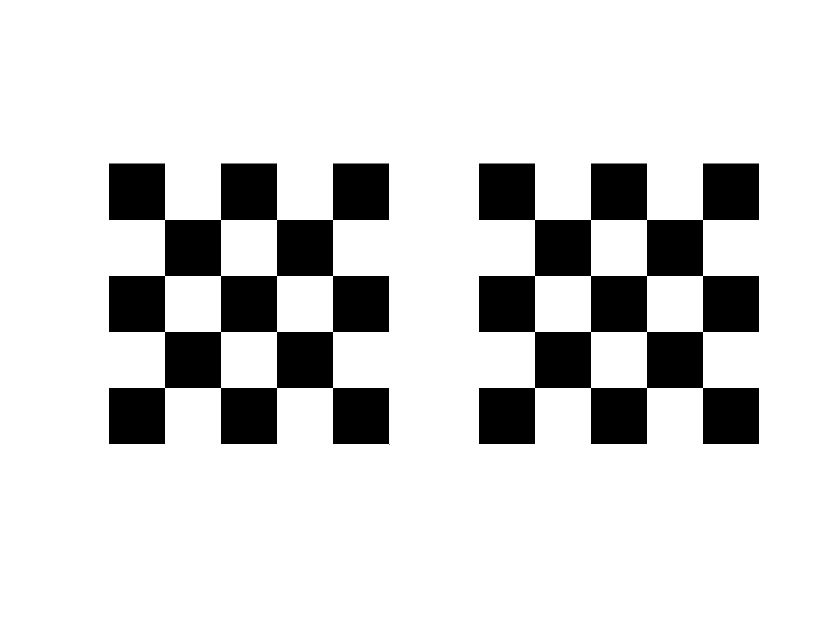

rxIm = reshape(dataRx, rows, []);
figure;
subplot(1,2,1)
imshow(rxIm)
subplot(1,2,2)
imshow(imBW)